  % generate a random next point
 
R = 1.5;
L = 1;
x_end = R*(1 - cos(L/R));
% x_end = 4
seg_i_x = linspace(0,x_end,100);
seg_i_y = - sqrt(R^2 - (seg_i_x - R).^2);
p2 = plot(seg_i_x,seg_i_y);
p2.LineWidth = 10;
p2.Color = 'b';
axis equal

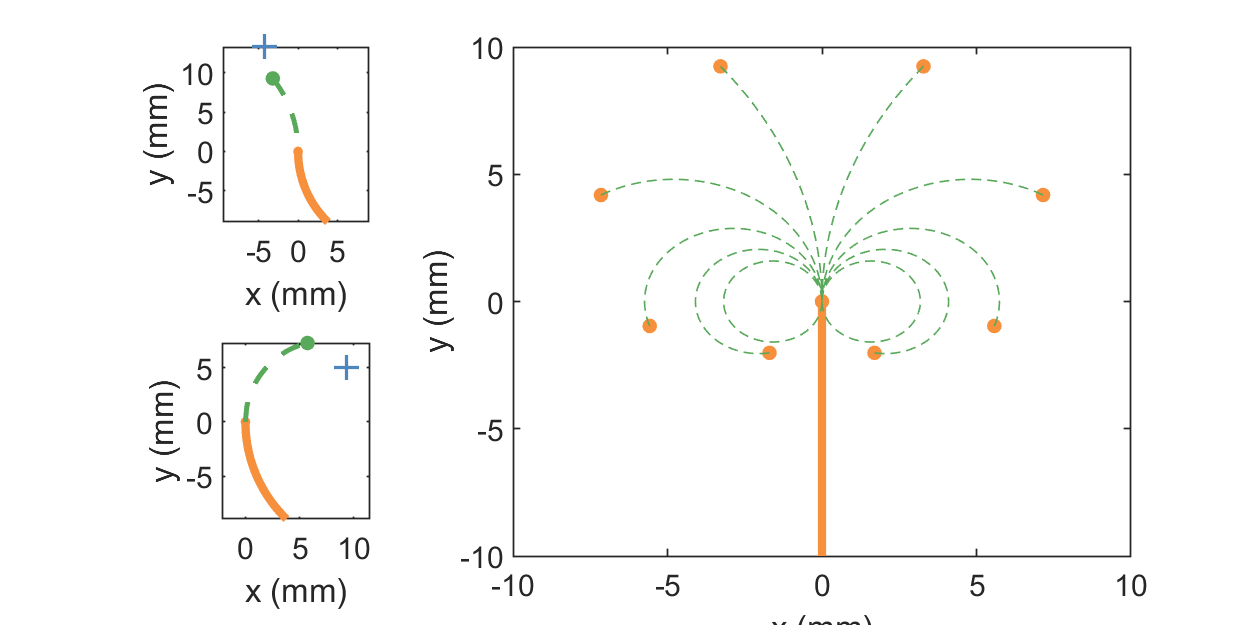

 
f = figure();
ax1 = subplot(2,3,1);
ax2 = subplot(2,3,4);
ax3 = subplot(2,3,[2,3,5,6]);

% define segment i
R = 12.5;
L = 10;
x_end = R*(1 - cos(L/R));
% x_end = 4
seg_i_x = linspace(0,x_end,100);
seg_i_y = - sqrt(R^2 - (seg_i_x - R).^2);

for ax = [ax1,ax2]
plot(ax,seg_i_x,seg_i_y, 'LineWidth',5,'Color',"#F7903D",...
    'Marker','.',...
    'MarkerIndices',1,'MarkerSize',20,...
    'MarkerEdgeColor',"#F7903D" ,'MarkerFaceColor',"#F7903D")
hold(ax,"on")
end


% axis 1
rho = 15;
rho_noisy = rho + 2.5*rand;
theta = L/rho;
theta_noisy = theta + 0.25*rand;

% Plot noisy data point
node_x_noisy = rho_noisy * cos(theta_noisy) - rho;
node_y_noisy = rho_noisy * sin(theta_noisy);
plot(ax1,node_x_noisy,node_y_noisy,'Marker','+',...
    'MarkerSize',15,'Color',"#4D85BD",...
    "LineWidth",2)

% Plot reference 
node_x = rho * cos(theta) - rho;
node_y = rho * sin(theta);
seg_i_x = linspace(node_x,0,50);
seg_i_y = sqrt(rho^2 - (seg_i_x + rho).^2);
plot(ax1,node_x,node_y,'Marker','.','MarkerSize',30,'Color',"#59A95A")
plot(ax1,seg_i_x,seg_i_y,'LineStyle','--','LineWidth',3,...
    'Color',"#59A95A")

% axis 2
rho = 7.5;
rho_noisy = rho + 2*(2*rand - 1);
theta = L/rho;
theta_noisy = theta + (2*rand - 1);

% Plot noisy data point
node_x_noisy = rho_noisy - rho_noisy * cos(theta_noisy);
node_y_noisy = rho_noisy * sin(theta_noisy);
plot(ax2,node_x_noisy,node_y_noisy,'Marker','+',...
    'MarkerSize',15,'Color',"#4D85BD",...
    "LineWidth",2)

% Plot reference 
node_x = rho - rho * cos(theta);
node_y = rho * sin(theta);
seg_i_x = linspace(0,node_x,50);
seg_i_y = sqrt(rho^2 - (seg_i_x - rho).^2);
plot(ax2,node_x,node_y,'Marker','.','MarkerSize',30,'Color',"#59A95A")
plot(ax2,seg_i_x,seg_i_y,'LineStyle','--','LineWidth',3,...
    'Color',"#59A95A")

% axis 3
% previous segment
prev_x = zeros(1,10);
prev_y = linspace(-10,0,10);
plot(ax3, prev_x, prev_y, 'LineWidth',5,'Color',"#F7903D",...
    'Marker','.',...
    'MarkerIndices',10,'MarkerSize',30,...
    'MarkerEdgeColor',"#F7903D" ,'MarkerFaceColor',"#F7903D")
hold(ax3,'on')

% reference data point
theta = -pi/2:0.7:pi/2;
rho = 2*L*cos(theta)./(pi - 2*theta);
node_x = rho.*cos(theta);
node_y = rho.*sin(theta);
plot(ax3,node_x,node_y,'LineStyle','none','Marker','.','MarkerSize',30,'Color',"#F7903D")

node_x = - rho.*cos(theta);
node_y = rho.*sin(theta);
plot(ax3,node_x,node_y,'LineStyle','none','Marker','.','MarkerSize',30,'Color',"#F7903D")


% Plot reference curve
for i = 1:1:length(rho)
    alpha = (2*theta(i)):0.01:pi;
    r = rho(i) / (2*cos(theta(i)));
    seg_i_x = r * cos(alpha) + r;
    seg_i_y = r * sin(alpha);
    plot(ax3,seg_i_x,seg_i_y,'LineStyle','--','LineWidth',1,...
        'Color',"#59A95A")

    seg_i_x = -seg_i_x;
    plot(ax3,seg_i_x,seg_i_y,'LineStyle','--','LineWidth',1,...
        'Color',"#59A95A")
end
% axis(ax3,[-1 1 -0.75 1])

for ax = [ax1,ax2,ax3]
ax.FontSize = 18;
ax.LineWidth = 1;
hold(ax,"off")
xlabel(ax,'x (mm)')
ylabel(ax,'y (mm)')
end
axis(ax1,'equal')
axis(ax2,'equal')
set(gcf,'Position',[100 100 1000 500])

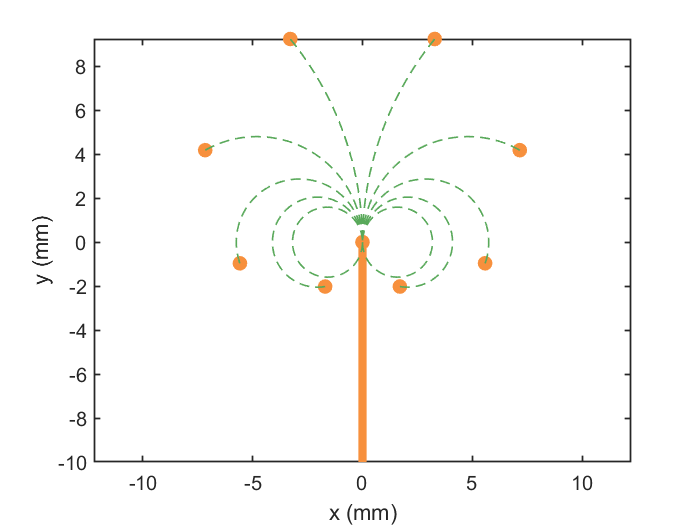

% previous segment
ax = gca;
R = 12.5;
L = 10;
prev_x = zeros(1,10);
prev_y = linspace(-10,0,10);
plot(ax, prev_x, prev_y, 'LineWidth',5,'Color',"#F7903D",...
    'Marker','.',...
    'MarkerIndices',10,'MarkerSize',30,...
    'MarkerEdgeColor',"#F7903D" ,'MarkerFaceColor',"#F7903D")
hold(ax,'on')

% reference data point
theta = -pi/2:0.7:pi/2;
rho = 2*L*cos(theta)./(pi - 2*theta);
node_x = rho.*cos(theta);
node_y = rho.*sin(theta);
plot(ax,node_x,node_y,'LineStyle','none','Marker','.','MarkerSize',30,'Color',"#F7903D")

node_x = - rho.*cos(theta);
node_y = rho.*sin(theta);
plot(ax,node_x,node_y,'LineStyle','none','Marker','.','MarkerSize',30,'Color',"#F7903D")


% Plot reference curve
for i = 1:1:length(rho)
    alpha = (2*theta(i)):0.01:pi;
    r = rho(i) / (2*cos(theta(i)));
    seg_i_x = r * cos(alpha) + r;
    seg_i_y = r * sin(alpha);
    plot(ax,seg_i_x,seg_i_y,'LineStyle','--','LineWidth',1,...
        'Color',"#59A95A")

    seg_i_x = -seg_i_x;
    plot(ax,seg_i_x,seg_i_y,'LineStyle','--','LineWidth',1,...
        'Color',"#59A95A")
end

ax.FontSize = 12;
ax.LineWidth = 1;
xlabel(ax,'x (mm)')
ylabel(ax,'y (mm)')
axis(ax,'equal')

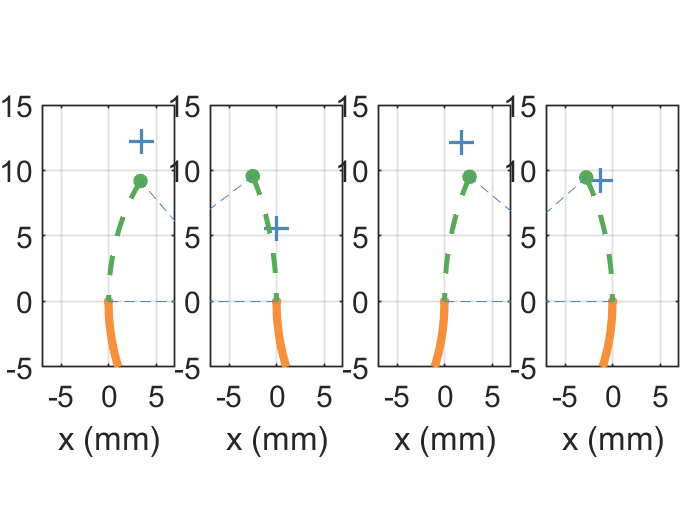

f = figure();
ax1 = subplot(1,4,1);
ax2 = subplot(1,4,2);
ax3 = subplot(1,4,3);
ax4 = subplot(1,4,4);

% define segment i
R = 12.5;
L = 10;
x_end = R*(1 - cos(L/R));
% x_end = 4
seg_i_x = linspace(0,x_end,100);
seg_i_y = - sqrt(R^2 - (seg_i_x - R).^2);
iter_idx = 1;

for ax = [ax1,ax2,ax3,ax4]

    if ax == ax1 || ax == ax2
        plot(ax,seg_i_x,seg_i_y, 'LineWidth',5,'Color',"#F7903D",...
        'Marker','.',...
        'MarkerIndices',1,'MarkerSize',20,...
        'MarkerEdgeColor',"#F7903D" ,'MarkerFaceColor',"#F7903D")
    else
        plot(ax,-seg_i_x,seg_i_y, 'LineWidth',5,'Color',"#F7903D",...
        'Marker','.',...
        'MarkerIndices',1,'MarkerSize',20,...
        'MarkerEdgeColor',"#F7903D" ,'MarkerFaceColor',"#F7903D")
    end
hold(ax,"on")

% define segment i+1 and noisy data
    rho = 15 + 5 * (2*rand - 1);
    rho_noisy = rho + 2.5* (2*rand - 1);
    theta = L/rho;
    theta_noisy = theta + 0.25*(2*rand - 1);
    
    % Plot noisy data point
    node_x_noisy = rho_noisy * cos(theta_noisy) - rho;
    node_y_noisy = rho_noisy * sin(theta_noisy);
    plot(ax,(-1)^(iter_idx)*node_x_noisy,node_y_noisy,'Marker','+',...
        'MarkerSize',15,'Color',"#4D85BD",...
        "LineWidth",2)
    
    % Plot reference 
    node_x = rho * cos(theta) - rho;
    node_y = rho * sin(theta);
    seg_next_x = linspace(node_x,0,50);
    seg_next_y = sqrt(rho^2 - (seg_next_x + rho).^2);
    plot(ax,(-1)^(iter_idx)*node_x,node_y,'Marker','.','MarkerSize',30,'Color',"#59A95A")
    plot(ax,(-1)^(iter_idx)*seg_next_x,seg_next_y,'LineStyle','--','LineWidth',3,...
        'Color',"#59A95A")
    
    % plot the guideline
    center_x = [0 (-1)^(iter_idx-1)*rho (-1)^(iter_idx)*node_x];
    center_y = [0 0 node_y];
    plot(ax, center_x, center_y, ...
        'LineStyle','--','Color','#4D85BD',...
        'MarkerIndices',2,...
        'MarkerFaceColor','#4D85BD',...
        'Marker','.','MarkerSize',20)

    iter_idx = iter_idx + 1;
end


for ax = [ax1,ax2,ax3,ax4]
ax.FontSize = 18;
hold(ax,"off")

xlabel(ax,'x (mm)')

axis(ax,[-7 7 -5 15])
% axis(ax,'equal')
% axis(ax,'tight')
box(ax,"on")
ax.LineWidth = 1;
grid(ax,'on')
end
ylabel(ax1,'y (mm)')
ax1.Position = [0.06 0.3 0.19 0.5];
ax2.Position = [0.3 0.3 0.19 0.5];
ax3.Position = [0.54 0.3 0.19 0.5];
ax4.Position = [0.78 0.3 0.19 0.5];



% set(gcf,'Position',[200 200 1200 600])